読み込み

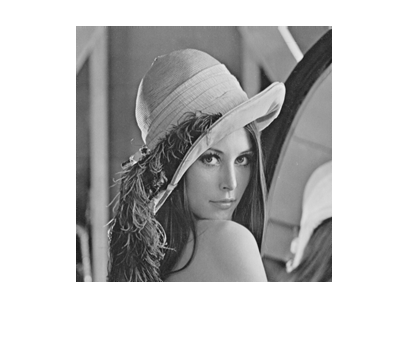

I=rgb2gray(imread("Lenna.bmp"));

imshow(I);

ガボールフィルタの適応

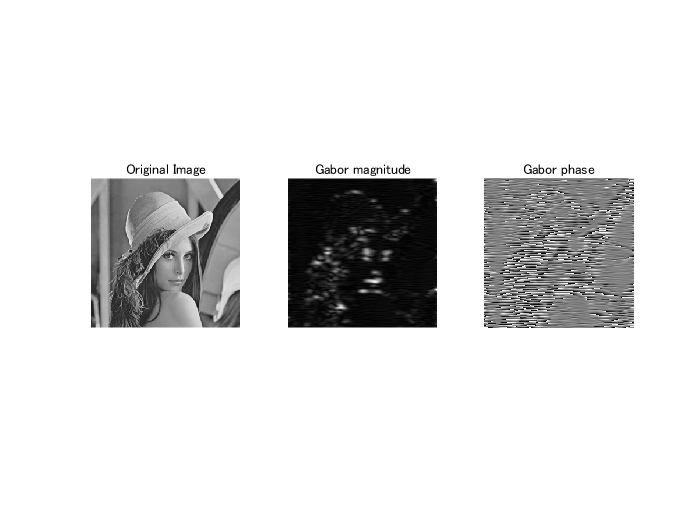

wavelength = 4;
orientation = 90;
[mag,phase] = imgaborfilt(I,wavelength,orientation);

figure
subplot(1,3,1);
imshow(I);
title('Original Image');
subplot(1,3,2);
imshow(mag,[])
title('Gabor magnitude');
subplot(1,3,3);
imshow(phase,[]);
title('Gabor phase');

A = imnoise(I,'salt & pepper', 0.02);

画像の評価

[peaksnr, snr] = psnr(A, I);

fprintf('\n The Peak-SNR value is %0.4f', peaksnr);


 The Peak-SNR value is 22.6417

fprintf('\n The SNR value is %0.4f \n', snr);


 The SNR value is 16.9538 
